# Lab 8 - Numerical Differentiation

Name: Lilith Janevska

## Problem 1 Answer

### a)

f = @(x) x.^3 + sin(x);
fprimetrue = @(x) 3.*x.^2+cos(x);
x = 1:1/1000:2;
E_n = [];
E_ratio = [1];
n = [];

hold on
plot(x,f(x),Color=[0,1,0],DisplayName="f(x)")

i = 1;
while i < 16
    h = 2^(-i);
    fprime = MyForwardDifference(f,x,h);
    
    
    plot(x,fprime,Color=[1-(i/15),0,0+(i/15)],DisplayName="h = "+string(2^(-i)))
    E_n = [E_n; max(max(abs(fprime-fprimetrue(x))))];
    n = [n;i];
    if i > 1
        E_ratio = [E_ratio; E_n(i)/E_n(i-1)]
    end

    i = i + 1;
end
plot(x,fprimetrue(x),Color=[0,0,0],LineWidth=1.5,DisplayName="f'(x)")
legend(gca,'show')
hold off

table(n,E_n,E_ratio)


function [result] = MyForwardDifference(f,x,h)
    y = (f(x+h)-f(x))/h;



    result = y;
end

Output:

15×3 table

    n        E_n        E_ratio
    __    __________    _______

     1        3.0445          1
     2        1.4537     0.4775
     3       0.70995    0.48836
     4       0.35077    0.49408
     5       0.17434    0.49701
     6      0.086907     0.4985
     7      0.043388    0.49925
     8      0.021678    0.49962
     9      0.010835    0.49981
    10     0.0054164    0.49991
    11     0.0027079    0.49995
    12     0.0013539    0.49998
    13    0.00067694    0.49999
    14    0.00033847    0.49999
    15    0.00016923        0.5

And a plot (because why not?):

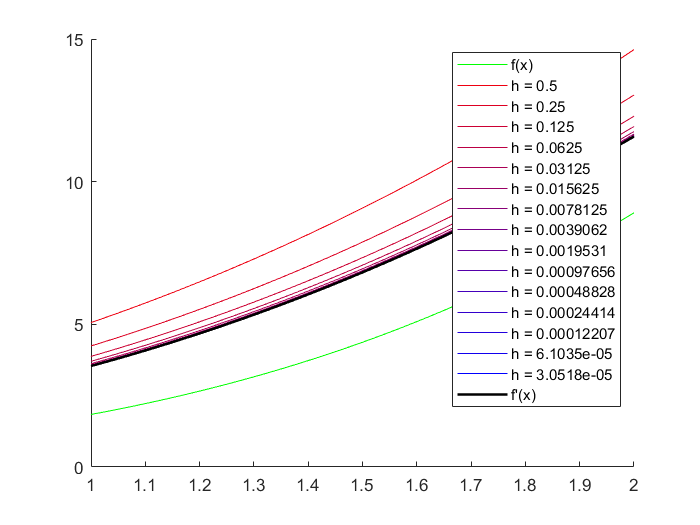

### b)

f = @(x) x.^3 + sin(x);
fprimetrue = @(x) 3.*x.^2+cos(x);
x = 1:1/1000:2;
E_n = [];
E_ratio = [1];
n = [];

hold on
plot(x,f(x),Color=[0,1,0],DisplayName="f(x)")

i = 1;
while i < 16
    h = 2^(-i);
    fprime = MyCenteredDifference(f,x,h);
    
    
    plot(x,fprime,Color=[1-(i/15),0,0+(i/15)],DisplayName="h = "+string(2^(-i)))
    E_n = [E_n; max(max(abs(fprime-fprimetrue(x))))];
    n = [n;i];
    if i > 1
        E_ratio = [E_ratio; E_n(i)/E_n(i-1)]
    end

    i = i + 1;
end
plot(x,fprimetrue(x),Color=[0,0,0],LineWidth=1.5,DisplayName="f'(x)")
legend(gca,'show')
hold off

table(n,E_n,E_ratio)


function [result] = MyCenteredDifference(f,x,h)
    y = (f(x+h)-f(x-h))/(2*h);



    result = y;
end

Output:

 15×3 table

    n        E_n        E_ratio
    __    __________    _______

     1       0.26712          1
     2      0.066821    0.25015
     3      0.016708    0.25004
     4     0.0041771    0.25001
     5     0.0010443       0.25
     6    0.00026107       0.25
     7    6.5268e-05       0.25
     8    1.6317e-05       0.25
     9    4.0793e-06       0.25
    10    1.0198e-06       0.25
    11    2.5495e-07       0.25
    12    6.3739e-08       0.25
    13     1.594e-08    0.25008
    14    3.9892e-09    0.25027
    15    1.0125e-09    0.25381

Another Plot:

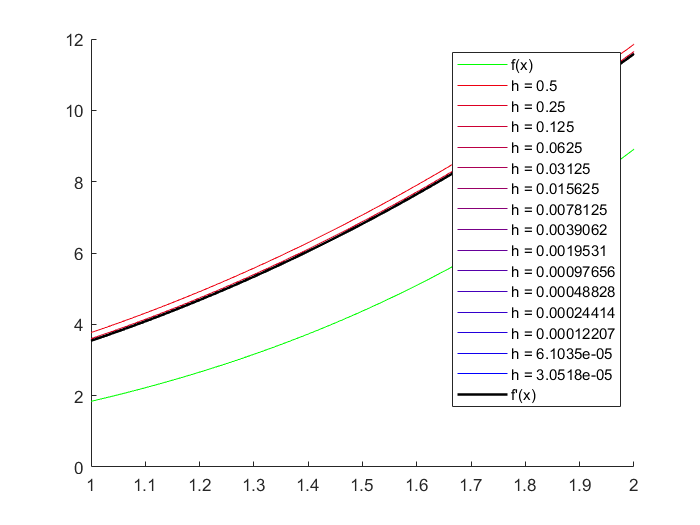

### c)

It's clear that the forward difference method is linear in terms of error reduction, as for every halving of the interval the error is also halved. However, with the centered method we have quadratic convergence as for every halving we reduce error by a fourth.

### d)

f = @(x) x.^3 + sin(x);
fprimetrue = @(x) 3.*x.^2+cos(x);
x = 1:1/1000:2;
p_for_n = [];
p_cen_n = [];
n = [];


i = 1;
while i < 16
    h = 2^(-i-1);
    %fcen = MyCenteredDifference(f,x,h);
    %ffor = MyForwardDifference(f,x,h);
    
    
    n = [n;i];
    if i > 2
        p_for = mean(log2(abs((MyForwardDifference(f,x,h*2)-MyForwardDifference(f,x,h*4))./(MyForwardDifference(f,x,h)-MyForwardDifference(f,x,h*2)))));
        p_cen = mean(log2(abs((MyCenteredDifference(f,x,h*2)-MyCenteredDifference(f,x,h*4))./(MyCenteredDifference(f,x,h)-MyCenteredDifference(f,x,h*2)))));
        p_for_n = [p_for_n; p_for];
        p_cen_n = [p_cen_n; p_cen];
    end

    i = i + 1;
end
p_for_n = [p_for_n;0;0]
p_cen_n = [p_cen_n;0;0]

table(n,p_for_n,p_cen_n)


function [result] = MyCenteredDifference(f,x,h)
    y = (f(x+h)-f(x-h))/(2*h);



    result = y;
end

function [result] = MyForwardDifference(f,x,h)
    y = (f(x+h)-f(x))/h;



    result = y;
end

Output:

15×3 table

    n     p_for_n    p_cen_n
    __    _______    _______

     1    1.0654     2.0001 
     2    1.0336          2 
     3     1.017          2 
     4    1.0086          2 
     5    1.0043          2 
     6    1.0022          2 
     7    1.0011          2 
     8    1.0005          2 
     9    1.0003          2 
    10    1.0001          2 
    11    1.0001          2 
    12         1     1.9997 
    13         1     2.0006 
    14         0          0 
    15         0          0 

Yep, seems to match my answer!

## Problem 2 Answer

f = @(x) 1./((x.^2)-(2.*x)+2);
fprimetrue = @(x) (2.*((3.*x.^2)-(6.*x)+2))./(((x.^2)-(2.*x)+2).^3);
x = 1:1/1000:2;
E_n = [];
E_ratio = [1];
n = [];

hold on
plot(x,f(x),Color=[0,1,0],DisplayName="f(x)")

i = 1;
while i < 21
    h = 2^(-i);
    fprime = MyCenteredSecondDifference(f,x,h);
    
    
    plot(x,fprime,Color=[1-(i/21),0,0+(i/21)],DisplayName="h = 1/"+string(2^(i)))
    E_n = [E_n; max(max(abs(fprime-fprimetrue(x))))];
    n = [n;i];
    if i > 1
        E_ratio = [E_ratio; E_n(i)/E_n(i-1)]
    end

    i = i + 1;
end
plot(x,fprimetrue(x),Color=[0,0,0],LineWidth=1.5,DisplayName="f'(x)")
legend(gca,'show','NumColumns',2)
hold off

table(n,E_n,E_ratio)


function [result] = MyCenteredSecondDifference(f,x,h)
    y = (f(x+h)-(2.*f(x))+f(x-h))/(h^2);

    result = y;
end

Output:

20×3 table

    n        E_n        E_ratio
    __    __________    _______

     1           0.4          1
     2       0.11765    0.29412
     3      0.030769    0.26154
     4     0.0077821    0.25292
     5     0.0019512    0.25073
     6    0.00048816    0.25018
     7    0.00012206    0.25005
     8    3.0517e-05    0.25001
     9    7.6294e-06       0.25
    10    1.9073e-06       0.25
    11    4.7712e-07    0.25015
    12    1.2435e-07    0.26063
    13    5.7574e-08    0.46298
    14    1.2797e-07     2.2228
    15    4.5339e-07     3.5428
    16     1.909e-06     4.2106
    17    7.9547e-06     4.1668
    18    3.1781e-05     3.9953
    19    0.00012604     3.9659
    20    0.00048889     3.8787

Another plot:

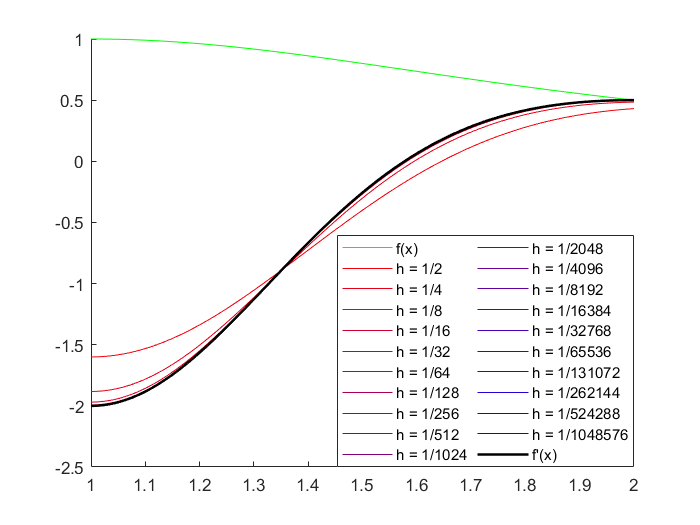

It's clear here that at the beginning the convergence is solidly quadratic, with every halving of the step leading to a fourth of the error. However, later it's the opposite and the error increases by roughly the square inverse of the step reduction. This function has nice continuous derivatives, no periodic nonsense, etc. Thefore, it's clear not an issue with this particular function but likely an issue with floating point percision. Sadly, Matlab doesn't support quadruple percision floats, but we can just check the error with single percission and get the following:

    20×3 table

    n        E_n        E_ratio
    __    __________    _______

     1           0.4          1
     2       0.11765    0.29412
     3      0.030769    0.26154
     4     0.0077821    0.25292
     5     0.0019512    0.25073
     6     0.0004882     0.2502
     7    0.00012211    0.25013
     8    3.0559e-05    0.25026
     9    7.6832e-06    0.25142
    10    1.9612e-06    0.25526
    11    5.3068e-07    0.27059
    12    1.7812e-07    0.33565
    13    1.0349e-07    0.58099
    14    1.7029e-07     1.6455
    15    4.5339e-07     2.6625
    16     1.909e-06     4.2106
    17    7.9547e-06     4.1668
    18    3.1781e-05     3.9953
    19    0.00012604     3.9659
    20    0.00048889     3.8787

Before, the first increase from the ratio was at n = 11, now it's at n = 7. Clearly a percision error.